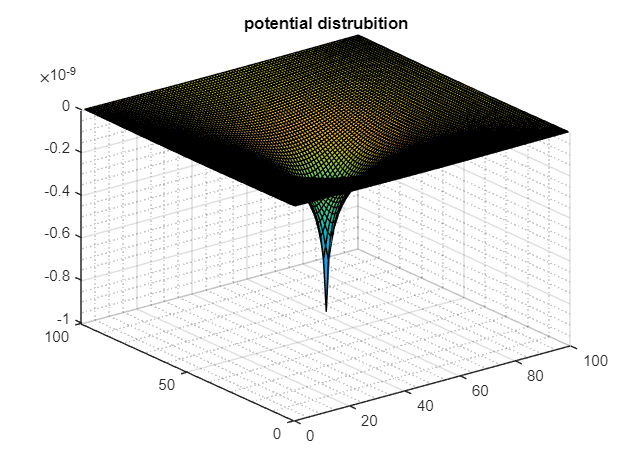

clc
clear
% N = point number between two integer
N = 100;

e = input("dielectric constant of the medium: ");
% I used k for ease of use, might be deleted 
k = input("constant coefficient of charge distribution: ");
pv = input("charge distribution (give ((N-1)*(N-1),1) matrix): ");
f = -k*pv/e;

% set dx = approximate differential length
dx =  1/N;
% first solve the Laplace's equation with finite difference approximation
A_diag0 =  eye(N) * (-4 / dx^2);
A_diag0 = A_diag0 + diag(ones(N-1,1), 1) / dx^2;
A_diag0 = A_diag0 + diag(ones(N-1,1), -1) / dx^2;
A_diag1 = eye(N) / dx^2;
% I realised program slows down here because of the size of the matrix.
% Since there are so many 0 entries, using sparse is more efficient
A = sparse(N*N , N*N);

% central diagonal entries
for i = 1:N
    A((i-1)*N+1:(i-1)*N+N, (i-1)*N+1:(i-1)*N+N) = A_diag0; 
end 

% upper and lower diagonal entries
for i = 2:N
    A((i-2)*N+1:(i-2)*N+N, (i-1)*N+1:(i-1)*N+N) = A_diag1;
    A((i-1)*N+1:(i-1)*N+N, (i-2)*N+1:(i-2)*N+N) = A_diag1;
end

% set boundary condition (Dirichlet boundary condition/some constant number)
V0x1 = input("V0x1, x axis lower boundary condition: ");
V0y1 = input("V0y1, y axis left hand side boundary condition: ");
V0x2 = input("V0x2, x axis upper boundary condition: ");
V0y2 = input("V0y2, y axis right hand side boundary condition: ");


% setting x axis lower boundary condition
for i=(N-1)*N+1:1:N*N
    V(i)=V0x1/dx^2;
end

% setting y axis left hand side boundary condition
for i=1:N:N*(N-1)+1
    V(i)=V0y1/dx^2;
end

% setting x axis upper boundary condition
for i=1:1:N
    V(i)=V0y2/dx^2;
end

% setting y axis right hand side boundary condition 
for i=N:N:(N*N)
    V(i)=V0x2/dx^2;
end

% finding potential
V = -A\f;
V = reshape(V, N, N);
surf(V)
grid minor
title("potential distrubition")


% finding electric field
figure;
x = linspace(0,1,(N));
y = x';
reshape(V.',1,[])

ans = 1.0e-09 *

   -0.0001   -0.0002   -0.0003   -0.0004   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0026   -0.0027   -0.0028   -0.0029   -0.0030   -0.0031   -0.0032   -0.0033   -0.0034   -0.0034   -0.0035   -0.0036   -0.0037   -0.0037   -0.0038   -0.0039   -0.0039   -0.0040   -0.0040   -0.0041   -0.0041   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042


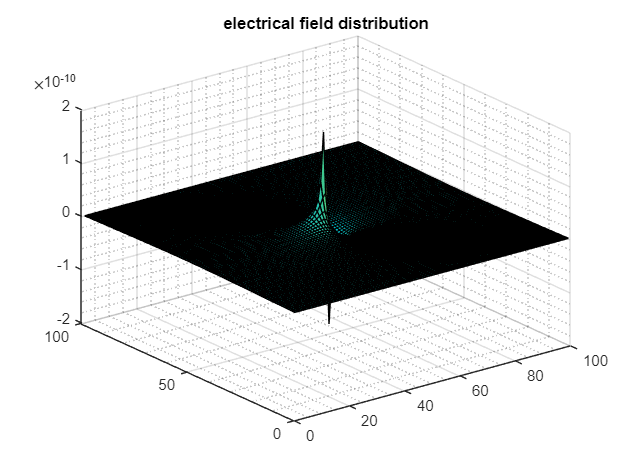

[EX,EY] = gradient(-V);
surf(EX,EY);
grid minor
title("electrical field distribution")

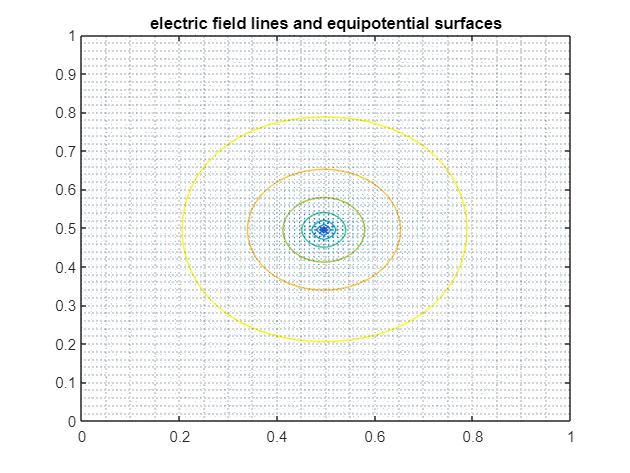


% electric field lines and equipotential surfaces
figure;
contour(x,y,V)
hold on
quiver(x,y,EX,EY)
grid minor
title("electric field lines and equipotential surfaces")



% e0 = 8.85*10^12

% point charge at the center
% reshape(diag([zeros(1,49) 100000 zeros(1,50)]).',[],1)

% uniform charge distribution
% ones(N*N,1)